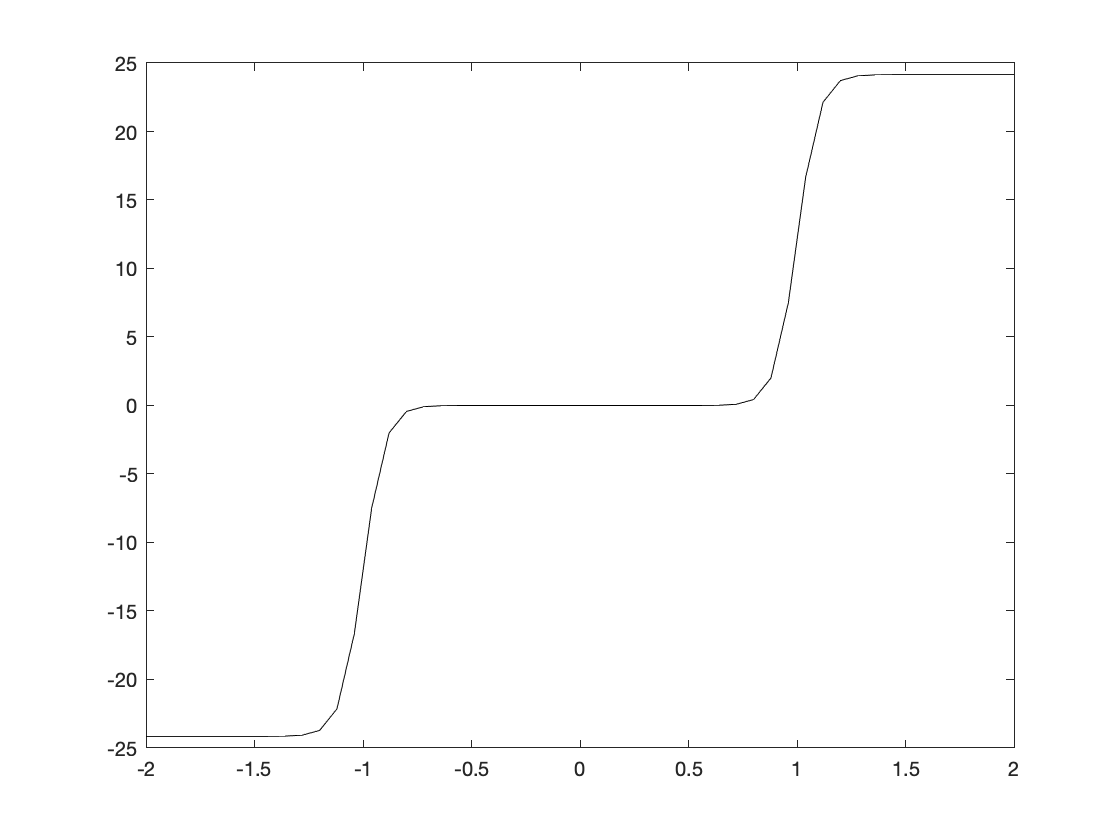

E0 = -5.5; 
Ef = -5;
gam1 = 0.1 ; 
gam2 = 0.1;
U = 0 ; %Constants (all MKS, except energy which is in eV) 
hbar = 1.06e-34;q = 1.6e-19;IE = (2*q*q)/hbar;
kT = .025; % Bias (calculate 101 voltage points in [-4 4] range) 
nV = 101;VV = linspace(-4,4,nV);dV = VV(2)-VV(1); N0 = 2/ (1 + exp((E0-Ef)/kT) ) ; 
for iV = 1:nV% Voltage loop 
    UU = 0;dU = 1;

    V = VV(iV);mu1 = Ef-(V/2);mu2 = Ef+(V/2); 

    while dU>1e-6%SCF 
        E = E0+UU;

        f1 = 1/(1+exp((E-mu1)/kT));f2 = 1/(1+exp((E-mu2)/kT)); NN = 2* ( (gam1*f1) + (gam2*f2))/(gam1 + gam2) ; % Charge 
        Uold = UU;UU = Uold+(.05*((U*(NN-N0))-Uold)); dU = abs (UU-Uold) ; [V UU dU] ;

    end

    curr = IE*gam1*gam2 *(f2-f1)/(gam1+gam2) ; 
    II(iV) = curr ;
    N(iV) = NN; 
end

[V NN] ;

G = diff(II)/dV;GG = [G(1) G] ; % Conductance 
h = plot(VV,II*10^6,'k');% Plot I-V
xlim([-2 2])

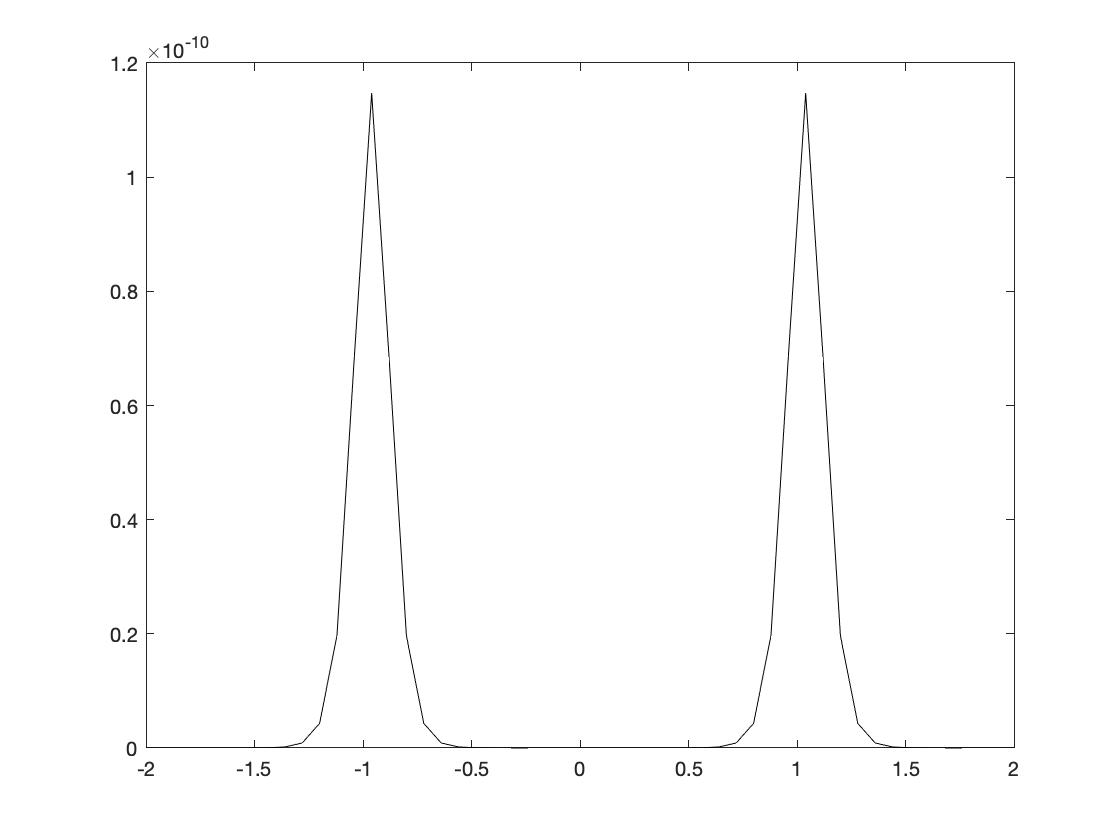

h4 = plot(VV,GG*10^-6, 'k');
xlim([-2 2])

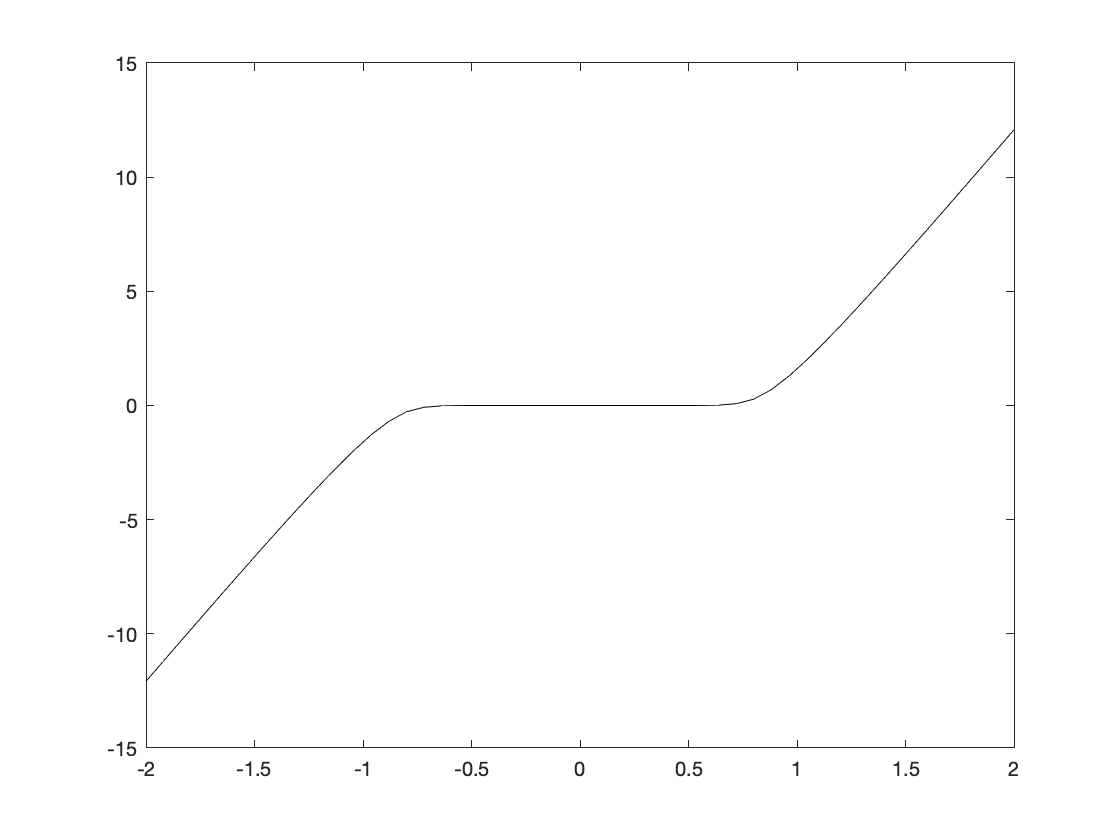



U = 1 ; %Constants (all MKS, except energy which is in eV) 
hbar = 1.06e-34;q = 1.6e-19;IE = (2*q*q)/hbar;
kT = .025; % Bias (calculate 101 voltage points in [-4 4] range) 
nV = 101;VV = linspace(-4,4,nV);dV = VV(2)-VV(1); N0 = 2/ (1 + exp((E0-Ef)/kT) ) ; 
for iV = 1:nV% Voltage loop 
    UU = 0;dU = 1;

    V = VV(iV);mu1 = Ef-(V/2);mu2 = Ef+(V/2); 

    while dU>1e-6%SCF 
        E = E0+UU;

        f1 = 1/(1+exp((E-mu1)/kT));f2 = 1/(1+exp((E-mu2)/kT)); NN = 2* ( (gam1*f1) + (gam2*f2))/(gam1 + gam2) ; % Charge 
        Uold = UU;UU = Uold+(.05*((U*(NN-N0))-Uold)); dU = abs (UU-Uold) ; [V UU dU] ;

    end

    curr = IE*gam1*gam2 *(f2-f1)/(gam1+gam2) ; 
    II(iV) = curr ;
    N(iV) = NN; 
end

[V NN] ;
figure;
G = diff(II)/dV;GG = [G(1) G] ; % Conductance 
h = plot(VV,II*10^6,'k');% Plot I-V
xlim([-2 2])

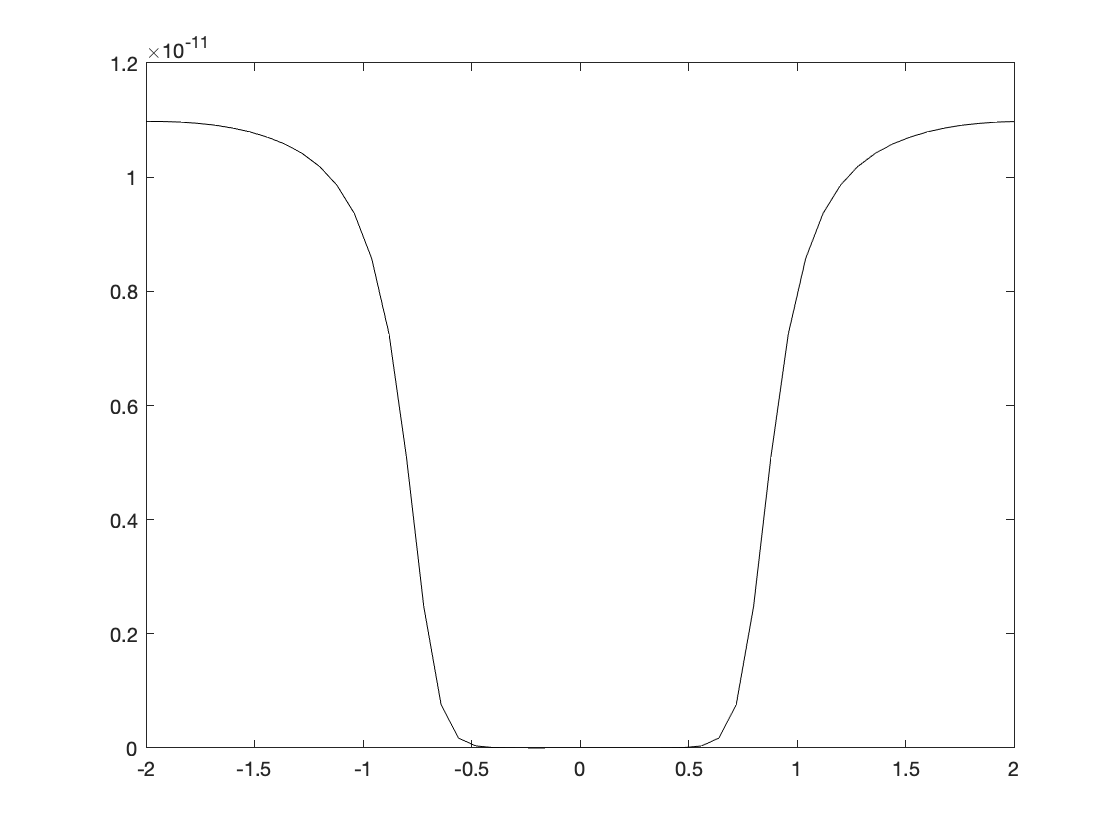


figure;
h4 = plot(VV,GG*10^-6, 'k');
xlim([-2 2])